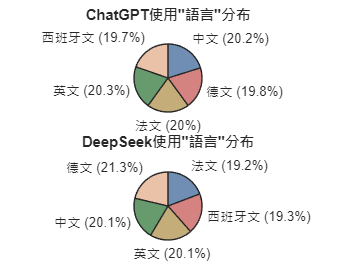

%比較不同ai使用國家分布
file = readtable("deepseek_vs_chatgpt.csv") ;

%分別抓取用不同模型的語言資料
gptfile=file(strcmp(file.AI_Platform, 'ChatGPT'), {'Language','Active_Users'});
deepseekfile=file(strcmp(file.AI_Platform, 'DeepSeek'), {'Language','Active_Users'});
gptUsers=groupsummary(gptfile, 'Language', 'sum','Active_Users');
dsUsers=groupsummary(deepseekfile, 'Language', 'sum','Active_Users');

subplot(2,1,1);
p=piechart(gptUsers.sum_Active_Users,gptUsers.Language);
title('ChatGPT使用"語言"分布');

subplot(2,1,2);
p=piechart(dsUsers.sum_Active_Users,dsUsers.Language);
title('DeepSeek使用"語言"分布');

%其他設定
colororder earth;%調色盤
p.DisplayOrder = "ascend";%升冪排序

gptRegion = file(strcmp(file.AI_Platform, 'ChatGPT'), 'Region');
gptRegion=gptRegion.Region;
[gptCountryTimes,gptcountry]=groupcounts(gptRegion);%計算各個國家使用GPT的數量

%繪圖的部分活腳本跑出來會很炸裂，請用command line跑
%piechart(gptCountryTimes,gptcountry);
%title('ChatGPT使用"國家"分布');
%legend(gptRegion.Region, 'Location', 'bestoutside'); 國家太多了

deepseekRegion = file(strcmp(file.AI_Platform, 'DeepSeek'), 'Region');
deepseekRegion=deepseekRegion.Region;
[dsCountryTimes,dscountry]=groupcounts(deepseekRegion);%計算各個國家使用deepseek的數量

%piechart(dsCountryTimes,dscountry);
%title('DeepSeekT使用"國家"分布');